# iEMG - Integrated EMG

iEMG is the sum of the absolute value of raw EMG data. We can think of it as the integral of the absolute value of our raw data. iEMG is used to determine a raise in signal power and amplitude.

[Mithbavkar, Shraddha Atul, and Milind Shantilal Shah. "Recognition of Emotion Through Facial Expressions Using EMG Signal." 2019 International Conference on Nascent Technologies in Engineering (ICNTE). IEEE, 2019.](https://drive.google.com/file/d/1z2df6YGj-S1I4xbYPOcqUqHkP70LQFSM/view?usp=sharing)

"When the absolute value of the signal is taken, noise will make the mathematical integral have a constant increase."

[https://www.biopac.com/application/emg-electromyography/advanced-feature/automated-emg-analysis/](https://www.biopac.com/application/emg-electromyography/advanced-feature/automated-emg-analysis/) 

iEMG = sum(abs(data_ch1),2)

iEMG = 409×1 single column vector
	1.0e+05 *

    1.2046
    1.3283
    1.2213
    0.3997
    0.5529
    0.6789
    0.6509
    1.7568
    1.7149
    0.4308


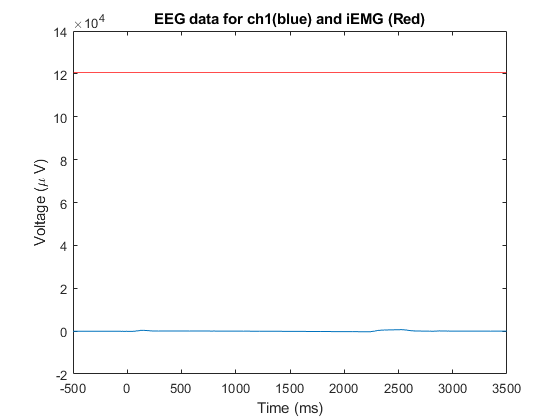

figure(1)
plot(times_ms, data_ch1(1,:)) %...data from ch1
hold on
%plot(times_ms,iEMG, 'r') %... iEMG performed on ch1 data
yline(iEMG(1,:), 'r');
xlabel("Time (ms)")  %Label the x-axis as time.
ylabel("Voltage (\mu V)") %Label the y-axis as voltage.
title("EEG data for ch1(blue) and iEMG (Red)")
hold off %Release the current plot.